clearvars
close all
clc

disp('Problem 2')

Problem 2


disp('d)')

d)


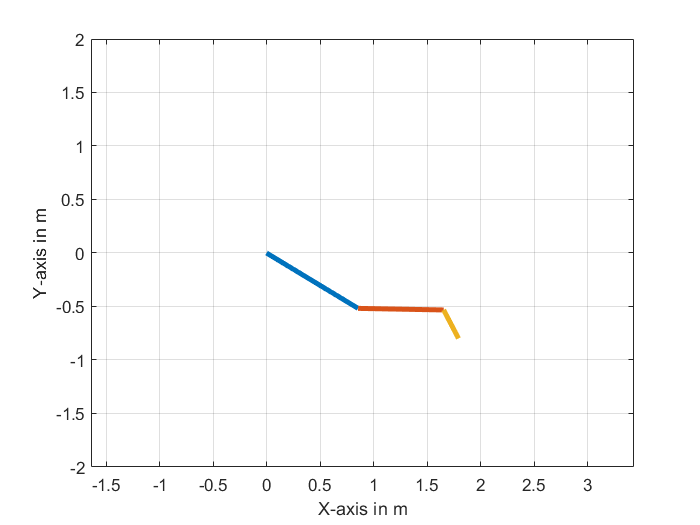

% Loop to run the animation of the robot
for t = 0:0.25:10 % 0 to 10 seconds with step of 0.25 second
    theta1 = sin(t);
    theta2 = 0.8*sin(0.7*t);
    theta3 = 2*sin(1.2*t);
    % Coordinate oF point O
    Ox = 0;
    Oy = 0;
    % Equation to calculate x and y coordinate of point A
    Ax = 1*cos(theta1);
    Ay = 1*sin(theta1);
    % Equation to calculate x and y coordinate of point B
    Bx = Ax + 0.8*cos(theta1 + theta2);
    By = Ay + 0.8*sin(theta1 + theta2);
    % Equation to calculate x and y coordinate of end point C
    Cx = Bx + 0.3*cos(theta1 + theta2 + theta3);
    Cy = By + 0.3*sin(theta1 + theta2 + theta3);
    % Plot all the link of the robot and their relationship  
    plot([Ox Ax], [Oy Ay], [Ax Bx], [Ay By], [Bx Cx], [By Cy], 'LineWidth',3);
    hold on % Hold the current plot
    grid on % Turn on grid in the plot
    axis ([-2 2 -2 2]) % Length of x, y axis
    axis equal % Scale the plot to be equal
    xlabel('X-axis in m')
    ylabel('Y-axis in m')
    drawnow
    hold off % Default mode
end